# Processing Event 2: 1 March 2011


% Initializing path of HDF5 file
clear all;
rootpath= 'C:\Users\nithin\Google Drive\Research\Projects\Paper 2\Data\Event 2\PFISR\'; 
fileNameStr = [rootpath,'20110301.001_lp_10sec-Ne.h5'];


## Extracting data

amisrData=read_amisr(fileNameStr);

## Creating magnetic field aligned coordinates

amisrData = aer_to_field_aligned_cartesian(amisrData,70);


## Interpolating data to field aligned coordinates

thisTimeStr = '1 Mar 2011 09:00';
timeMinIndx = find_time(amisrData.time(1,:),thisTimeStr);
thisTimeStr = '1 Mar 2011 10:00';
timeMaxIndx = find_time(amisrData.time(1,:),thisTimeStr);
for itime = timeMinIndx:timeMaxIndx
    ne=amisrData.electronDensity(:,:,itime);
    F = scatteredInterpolant(amisrData.origCartCoords.xEast(:),amisrData.origCartCoords.yNorth(:),amisrData.origCartCoords.zUp(:),ne(:),'linear','none');
    amisrData.magElectronDensity(:,:,itime) = F(amisrData.magCartCoords.xEast,amisrData.magCartCoords.yNorth,amisrData.magCartCoords.zUp);
end
%% need to think more about this interpolation

## Plot

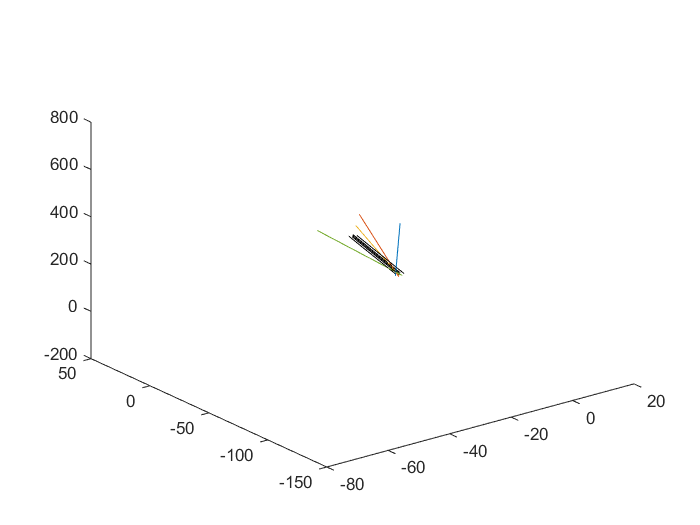

figure; plot3(amisrData.cartCoords.xEast,amisrData.cartCoords.yNorth,amisrData.cartCoords.zUp);hold on; plot3(amisrData.magCartCoords.xEast,amisrData.magCartCoords.yNorth,amisrData.magCartCoords.zUp,'k');

## Creating Energy Spectra

% PFISR Location
lat = amisrData.site.latitude;
lon = amisrData.site.longitude;
% Energy spectra
energyBin = logspace(3,6,30)';

nBeams = amisrData.nBeams;
timeRange = timeMinIndx:1:timeMaxIndx;
time = amisrData.time(1,timeRange);
for iBeam = 1:1:nBeams
    minAltNo = find_altitude(amisrData.altitude(:,iBeam),70);
    maxAltNo = find_altitude(amisrData.altitude(:,iBeam),200);
    coordRange = minAltNo:1:maxAltNo;
    Ne = squeeze(amisrData.magElectronDensity(coordRange,iBeam,timeRange));
    alt = amisrData.altitude(coordRange,iBeam);
    q = get_production_rate(Ne,alt,time,2); 
    A = get_energy_dep_matrix(alt,energyBin,lat,lon,time(round(length(time)/2)));% Approximation - should iterate time
    dataInv(iBeam) = get_inverted_flux(q,time,alt,energyBin,A);
    magcoords(:,iBeam,:) = [amisrData.magCartCoords.xEast(coordRange,iBeam),amisrData.magCartCoords.yNorth(coordRange,iBeam),amisrData.magCartCoords.zUp(coordRange,iBeam)];
    iBeam/nBeams
end

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In get_energy_dep_matrix (line 58)
  In 

0.3125 %0.99895
0.625 %1.3263
0.9375 %1.3655
1.25 %0.9533
1.5625 %0.98977
1.875 %0.69904
2.1875 %1.1055
2.5 %0.95487
2.8125 %0.87193
3.125 %1.2969
3.4375 %1.0618
3.75 %0.88615
4.0625 %1.5762
4.375 %0.87592
4.6875 %1.0605
5 %1.0906
5.3125 %1.5112
5.625 %1.1255
5.9375 %1.1675
6.25 %0.85035
6.5625 %1.638
6.875 %1.2471
7.1875 %1.2076
7.5 %1.3999
7.8125 %0.94607
8.125 %1.5447
8.4375 %0.69939
8.75 %1.4861
9.0625 %1.1269
9.375 %1.2923
9.6875 %1.64
10 %1.0689
10.3125 %1.8016
10.625 %1.17
10.9375 %1.702
11.25 %0.82249
11.5625 %1.617
11.875 %1.1095
12.1875 %1.7111
12.5 %0.78865
12.8125 %0.75173
13.125 %1.3418
13.4375 %1.034
13.75 %0.95634
14.0625 %1.3478
14.375 %1.3568
14.6875 %1.2304
15 %1.7425
15.3125 %1.0863
15.625 %0.89371
15.9375 %1.0645
16.25 %1.0076
16.5625 %1.0661
16.875 %0.88827
17.1875 %0.97602
17.5 %1.6395
17.8125 %1.1913
18.125 %1.331
18.4375 %1.268
18.75 %1.1933
19.0625 %0.74228
19.375 %1.4397
19.6875 %1.1331
20 %1.3013
20.3125 %0.93939
20.625 %0.70445
20.9375 %1.1997
21.25 %1.1644


ans = 0.2000

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In get_energy_dep_matrix (line 58)
  In 

0.3125 %0.95056
0.625 %1.9003
0.9375 %1.7131
1.25 %6.415
1.5625 %1.3652
1.875 %1.0635
2.1875 %0.81586
2.5 %1.8663
2.8125 %1.5382
3.125 %1.027
3.4375 %0.7938
3.75 %1.4051
4.0625 %1.4182
4.375 %1.2686
4.6875 %1.1132
5 %0.8471
5.3125 %1.4766
5.625 %1.6696
5.9375 %1.4999
6.25 %1.8319
6.5625 %1.0758
6.875 %0.77479
7.1875 %0.69906
7.5 %1.225
7.8125 %0.69935
8.125 %0.95752
8.4375 %1.3542
8.75 %1.5689
9.0625 %1.4384
9.375 %1.5955
9.6875 %1.2983
10 %1.0609
10.3125 %1.9187
10.625 %1.5985
10.9375 %1.1307
11.25 %2.0465
11.5625 %1.5509
11.875 %6.0509
12.1875 %1.5667
12.5 %1.4088
12.8125 %2.1216
13.125 %0.92257
13.4375 %2.2
13.75 %1.172
14.0625 %0.69976
14.375 %1.4363
14.6875 %2.299
15 %0.96654
15.3125 %0.99734
15.625 %1.7194
15.9375 %1.2911
16.25 %1.0734
16.5625 %0.79914
16.875 %1.1948
17.1875 %1.0418
17.5 %1.4391
17.8125 %0.6963
18.125 %1.2391
18.4375 %1.0157
18.75 %1.7364
19.0625 %2.0638
19.375 %1.3125
19.6875 %1.1886
20 %1.7818
20.3125 %0.75653
20.625 %2.2801
20.9375 %1.3121
21.25 %1.9003
21.562

ans = 0.4000

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In get_energy_dep_matrix (line 58)
  In 

0.3125 %0.7
0.625 %1.0346
0.9375 %1.2536
1.25 %5.0781
1.5625 %0.99069
1.875 %0.7
2.1875 %0.70988
2.5 %1.2155
2.8125 %1.3934
3.125 %1.0122
3.4375 %0.69989
3.75 %1.27
4.0625 %1.1863
4.375 %0.88038
4.6875 %0.88177
5 %0.79922
5.3125 %1.0515
5.625 %1.3131
5.9375 %1.3329
6.25 %1.2137
6.5625 %1.3527
6.875 %0.7
7.1875 %0.70431
7.5 %0.95062
7.8125 %0.74753
8.125 %0.86448
8.4375 %1.3403
8.75 %1.5656
9.0625 %0.98596
9.375 %1.1631
9.6875 %1.1932
10 %0.88636
10.3125 %1.5369
10.625 %1.3344
10.9375 %1.2492
11.25 %1.3845
11.5625 %1.644
11.875 %6.5913
12.1875 %1.7539
12.5 %0.9013
12.8125 %1.5019
13.125 %0.85032
13.4375 %0.80305
13.75 %0.90713
14.0625 %1.1103
14.375 %1.2667
14.6875 %1.3509
15 %0.88683
15.3125 %0.93523
15.625 %1.419
15.9375 %1.0619
16.25 %1.0478
16.5625 %0.89557
16.875 %0.96247
17.1875 %0.95045
17.5 %1.5599
17.8125 %0.69987
18.125 %1.1427
18.4375 %1.1501
18.75 %1.3564
19.0625 %1.031
19.375 %1.6518
19.6875 %0.94457
20 %1.3587
20.3125 %0.7
20.625 %1.794
20.9375 %1.257
21.25 %1.4156
21.5625

ans = 0.6000

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In get_energy_dep_matrix (line 58)
  In 

0.3125 %1.477
0.625 %1.5661
0.9375 %1.7088
1.25 %1.2137
1.5625 %1.3257
1.875 %1.1691
2.1875 %0.96495
2.5 %1.0409
2.8125 %1.7153
3.125 %1.4071
3.4375 %1.2005
3.75 %1.4617
4.0625 %2.0383
4.375 %1.3488
4.6875 %1.3855
5 %1.3208
5.3125 %1.2617
5.625 %1.1531
5.9375 %2.2782
6.25 %1.5518
6.5625 %2.2923
6.875 %1.226
7.1875 %1.1022
7.5 %1.344
7.8125 %1.2657
8.125 %1.4525
8.4375 %1.3849
8.75 %1.8589
9.0625 %1.1613
9.375 %1.4416
9.6875 %1.582
10 %1.3463
10.3125 %1.4789
10.625 %1.5155
10.9375 %2.005
11.25 %1.2437
11.5625 %2.2777
11.875 %1.4061
12.1875 %2.6676
12.5 %1.3592
12.8125 %1.3121
13.125 %1.4127
13.4375 %1.1877
13.75 %1.437
14.0625 %2.075
14.375 %1.7563
14.6875 %1.3823
15 %1.2544
15.3125 %1.535
15.625 %1.3912
15.9375 %1.2713
16.25 %1.7717
16.5625 %1.7162
16.875 %1.3638
17.1875 %1.2267
17.5 %2.2641
17.8125 %1.4989
18.125 %1.677
18.4375 %1.944
18.75 %1.5891
19.0625 %1.3876
19.375 %2.1481
19.6875 %1.509
20 %1.4504
20.3125 %1.455
20.625 %1.3802
20.9375 %1.316
21.25 %1.5048
21.5625 %1.2492
21.875

ans = 0.8000

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In get_energy_dep_matrix (line 58)
  In 

0.3125 %1.0522
0.625 %0.74221
0.9375 %1.1184
1.25 %1.0407
1.5625 %0.91439
1.875 %0.71761
2.1875 %0.86654
2.5 %0.79021
2.8125 %1.5
3.125 %1.773
3.4375 %0.93981
3.75 %1.0104
4.0625 %1.7284
4.375 %1.0294
4.6875 %1.0944
5 %1.095
5.3125 %1.0695
5.625 %1.4457
5.9375 %1.5575
6.25 %1.022
6.5625 %1.1981
6.875 %1.2176
7.1875 %0.69977
7.5 %1.0803
7.8125 %0.84116
8.125 %1.0462
8.4375 %1.0614
8.75 %1.4961
9.0625 %0.90604
9.375 %0.781
9.6875 %1.0331
10 %1.0697
10.3125 %1.2253
10.625 %0.94513
10.9375 %1.3624
11.25 %0.92577
11.5625 %1.6846
11.875 %1.0573
12.1875 %1.6769
12.5 %1.1922
12.8125 %1.0381
13.125 %0.84644
13.4375 %1.1721
13.75 %1.2377
14.0625 %1.3486
14.375 %1.2705
14.6875 %1.113
15 %1.133
15.3125 %0.8014
15.625 %0.88873
15.9375 %0.92665
16.25 %1.217
16.5625 %1.1863
16.875 %0.7
17.1875 %0.85605
17.5 %1.4434
17.8125 %1.2191
18.125 %0.85277
18.4375 %0.87251
18.75 %0.75089
19.0625 %0.69952
19.375 %1.6005
19.6875 %0.96258
20 %1.2745
20.3125 %1.1067
20.625 %1.0519
20.9375 %1.2793
21.25 %1.1012
21.

ans = 1

## Plot Energy Spectra

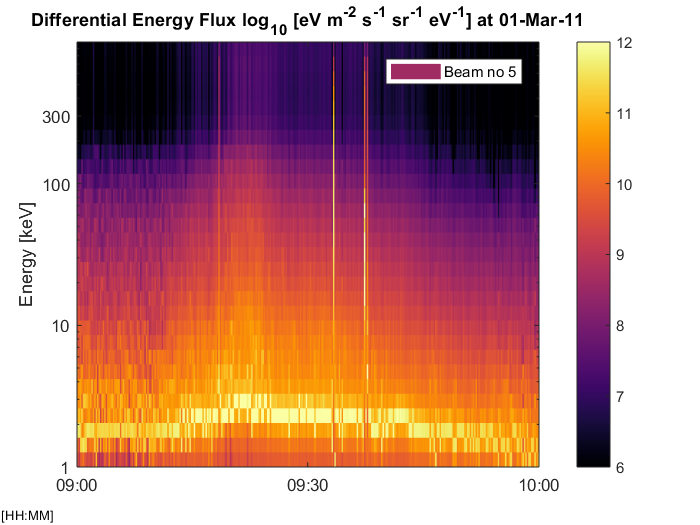

avgEnergyFlux = zeros(size(dataInv(1).energyFlux));
for iBeam = 1:1:nBeams
    avgEnergyFlux = avgEnergyFlux + dataInv(iBeam).energyFlux;
end
avgEnergyFlux=avgEnergyFlux/nBeams;

figure;
colormap(inferno);
plot_2D_time_series(time,dataInv(iBeam).energyBin/1000,log10(dataInv(iBeam).energyFlux),1/2,3);
caxis([6 12]);
colorbar;
ylabel('Energy [keV]');
set(gca,'YTick',[1,10,100,300]);
legend(['Beam no ',num2str(iBeam)]);

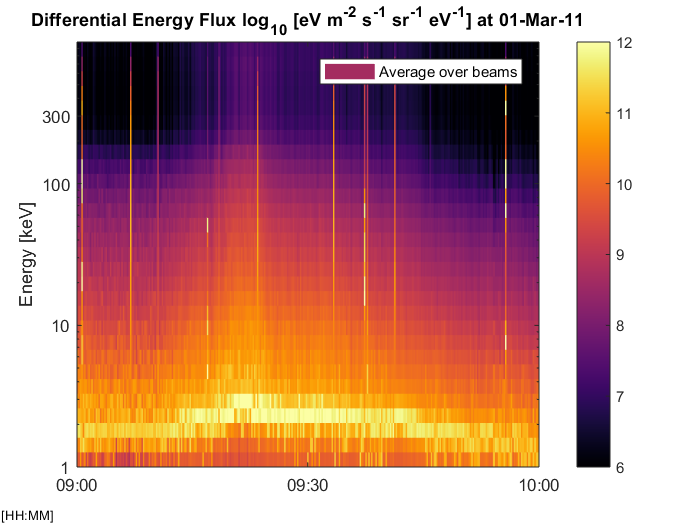


figure;
colormap(inferno);
plot_2D_time_series(time,dataInv(iBeam).energyBin/1000,log10(avgEnergyFlux),1/2,3);
caxis([6 12]);
colorbar;
ylabel('Energy [keV]');
set(gca,'YTick',[1,10,100,300]);
legend('Average over beams');

## Plot 2D energy flux maps

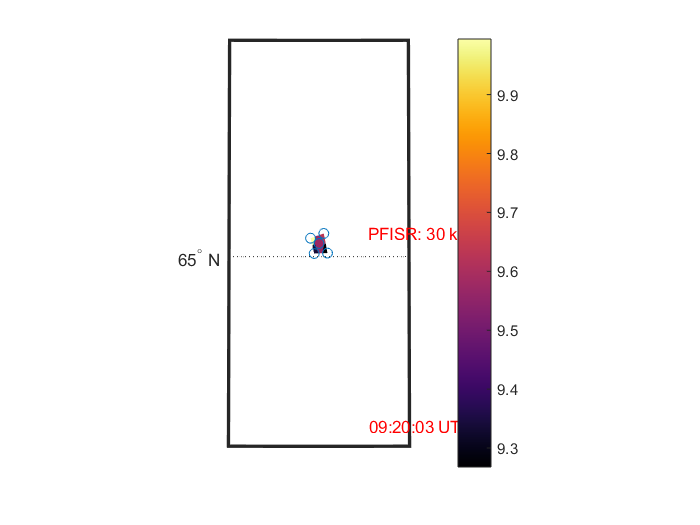

timeNo = find_time(dataInv(1).time,'01 Mar 2011 9:20');
figure;colormap(inferno);
plot_2D_energy_slice_geodetic_v1(dataInv,amisrData,magcoords,energyBin,nBeams,timeNo,120,30);
colorbar;

        % plot_2D_energy_slice_geodetic(dataInv,)


## Tests

## 1. Plot 2D Time Series Data (Test)

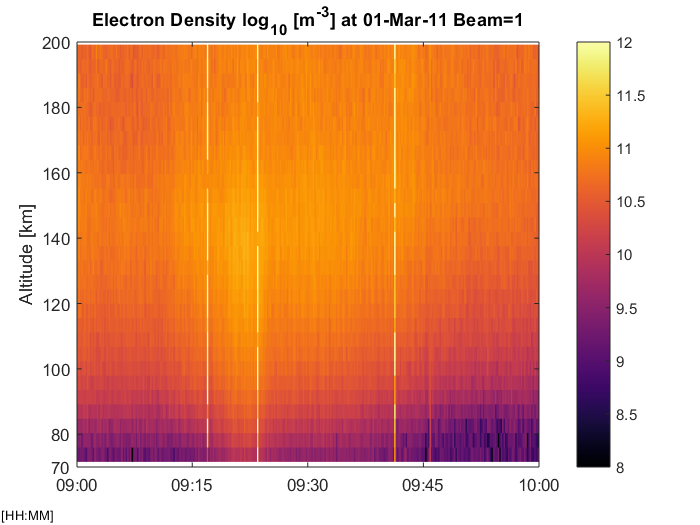

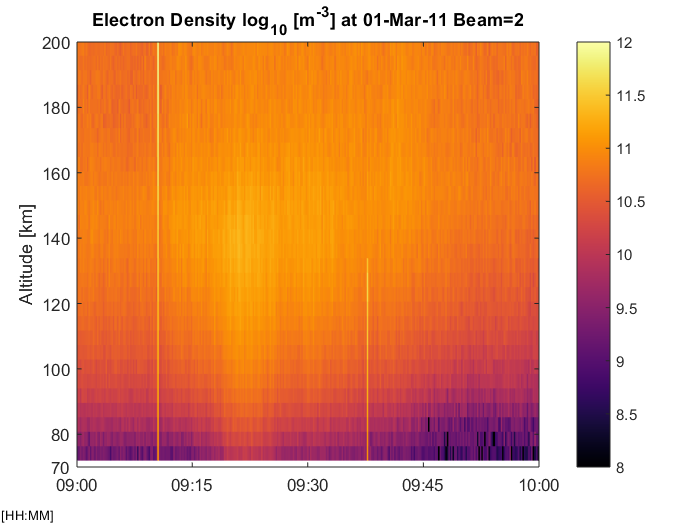

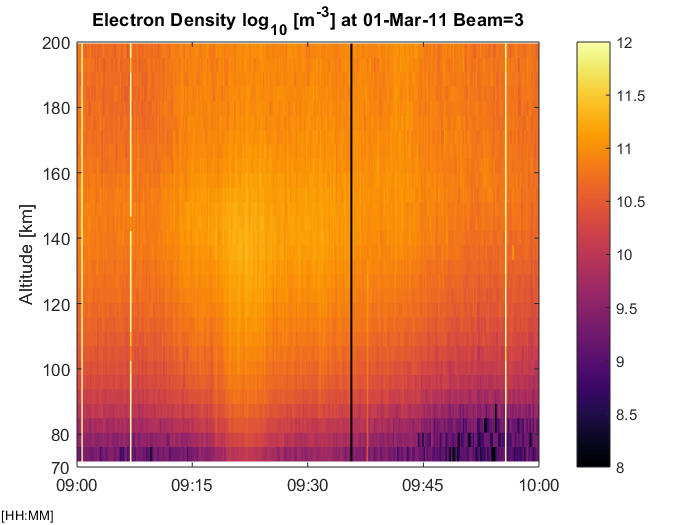

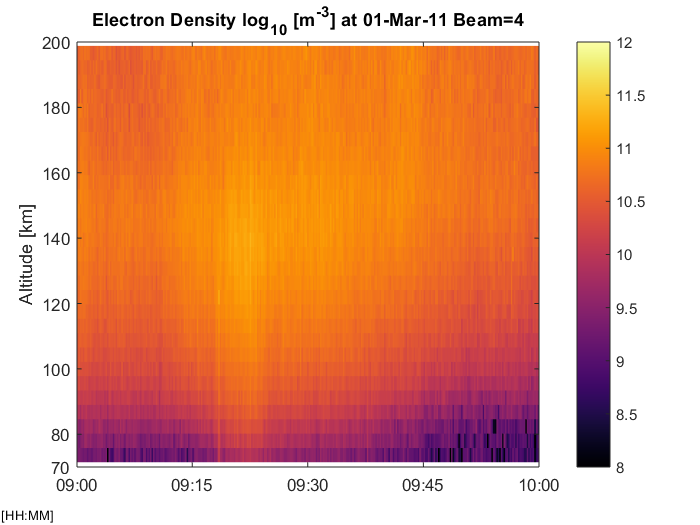

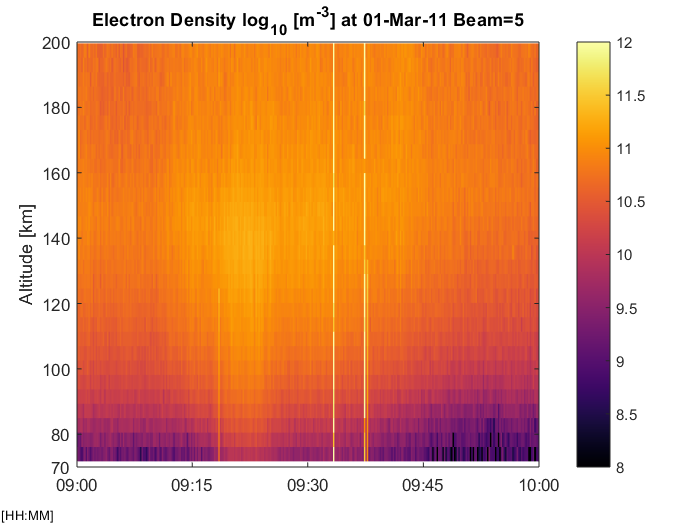

for iBeam = 1:1:5
    
    figure;
    colormap(inferno);
    dateMinStr = '1 Mar 2011 9:00';
    dateMaxStr = '1 Mar 2011 10:00';
    minAltNo = find_altitude(data.altitude(:,iBeam),70);
    maxAltNo = find_altitude(data.altitude(:,iBeam),200);
    plot_2D_time_series(data.time(1,:),data.altitude(minAltNo:maxAltNo,iBeam),log10(squeeze(data.electronDensity(minAltNo:maxAltNo,iBeam,:))),0.25,1,dateMinStr, dateMaxStr);
    colorbar;
    caxis([8 12]);
    title(['Electron Density log_1_0 [m^-^3] at 01-Mar-11 Beam=',num2str(iBeam)]);
    set(gca,'YTick',[70 80 100 120 140 160 180 200]);
    set(gca,'YLim',[70 200]);
end

## 2. Plot Altitude Profile (Test)

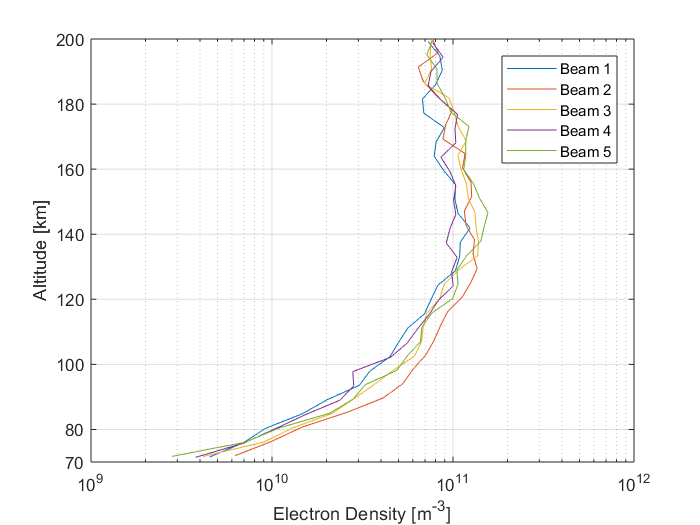

figure;
for iBeam = 1:1:5
    colormap(inferno);
    timeStr = '1 Mar 2011 9:30';
%     timeNo = find_time(data.time(1,:),timeStr);
    minAltNo = find_altitude(data.altitude(:,iBeam),70);
    maxAltNo = find_altitude(data.altitude(:,iBeam),200);
%     plot_2D_time_series(data.time(1,:),data.altitude(minAltNo:maxAltNo,iBeam),log10(squeeze(data.electronDensity(minAltNo:maxAltNo,iBeam,:))),0.25,1,dateMinStr, dateMaxStr);
    plot_1D_time_slice(data.time(1,:),data.altitude(minAltNo:maxAltNo,iBeam),data.electronDensity(minAltNo:maxAltNo,iBeam,:),timeStr,1);
    hold on;
end
legend('Beam 1','Beam 2','Beam 3', 'Beam 4', 'Beam 5');
%     title(['Electron Density log_1_0 [m^-^3] at 01-Mar-11 Beam=',num2str(iBeam)]);
    set(gca,'YTick',[70 80 100 120 140 160 180 200]);
    set(gca,'YLim',[70 200]);

## 3. MSIS Test

time = data.time(1,1:100:end);
latitude = 65.12;
longitude = -147.47;
alt = 80;

[D, T, F10_7_USED, AP_USED] = msis(time, latitude, longitude, alt);
nO      = D(:,1);
nN2     = D(:,2);
nO2     = D(:,3);
density = D(:,4);

Studying how the MSIS density varies through time at PFISR location. 

**MSIS Test Plots**

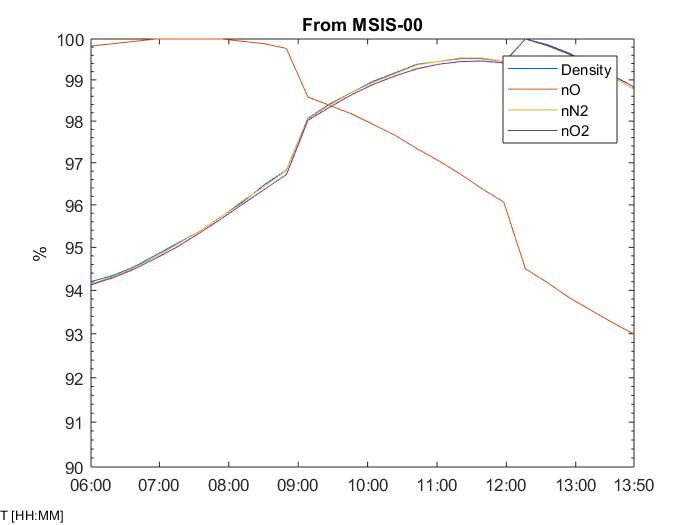


figure;
semilogy(time,100*density/max(density));
hold on;
semilogy(time,100*nO/max(nO));
hold on;
semilogy(time,100*nN2/max(nN2));
hold on;
semilogy(time,100*nO2/max(nO2));
hold on;
label_time_axis(time, true, 1);
ylim([90,100]);
ylabel('%')
legend('Density','nO','nN2','nO2');
title('From MSIS-E-90');

## 4. Energy Inversion Forward model Test


time = data.time(1,1000);
alt = (60:1:200)';
energyBin = (1:1:1000)'*1000; % 1 to 1000 keV 
[D, T, F10_7_USED, AP_USED] = msis(time, latitude, longitude, alt);
nO      = D(:,1);
nN2     = D(:,2);
nO2     = D(:,3);
density = D(:,4);


Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 93)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFile
 

## Plot the forward model

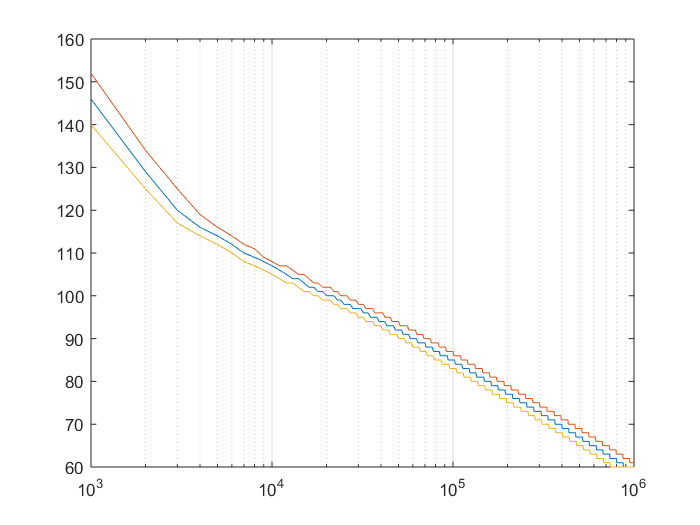

ans = 1

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 111)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFil

ans = 1.3195

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 111)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFil

ans = 0.7579

Using "ionization_profile_matrix" from:
> In ionization_profile_matrix (line 46)
  In LiveEditorEvaluationHelperE199149965 (line 111)
  In matlab.internal.editor.Evaluator/evalFile
  In matlab.internal.editor.Evaluator/evaluateCodeForFil

figure;
for i=1:1:3
    switch i
        case 1
            density1 = density;
            nN2_1 = nN2;
            nO2_1 = nO2;
        case 2
            density1=density*2^(2/5);   % Temperature halved & adiabatic atmosphere
            nN2_1 = nN2/10;
            nO2_1 = nO2/10;
        case 3
            density1=density*0.5^(2/5);  % Temperature is doubled
            nN2_1 = nN2*10;
            nO2_1 = nO2*10;
    end
density1(1)/density(1)
[A] = ionization_profile_matrix(alt,energyBin,nO,nN2,nO2,density1,1); % [cm-1 eV]

% Converting to SI units
A = (100)*A; %[m-1 eV]

[maxAVal,maxAltIndex] = max(A);
 semilogx(energyBin,alt(maxAltIndex));
 hold on;
end

legend('T* = T', 'T* = T/2', 'T* = 2T');